function images = loadMNISTImages(filename)
    fid = fopen(filename, 'rb');

    magic = fread(fid, 1, 'int32', 0, 'ieee-be');
    numImages = fread(fid, 1, 'int32', 0, 'ieee-be');
    numRows = fread(fid, 1, 'int32', 0, 'ieee-be');
    numCols = fread(fid, 1, 'int32', 0, 'ieee-be');

    images = fread(fid, inf, 'unsigned char');
    fclose(fid);

    images = reshape(images, numCols * numRows, numImages);
    images = double(images) / 255;
end

function labels = loadMNISTLabels(filename)
    fid = fopen(filename, 'rb');

    magic = fread(fid, 1, 'int32', 0, 'ieee-be');
    numLabels = fread(fid, 1, 'int32', 0, 'ieee-be');

    labels = fread(fid, inf, 'unsigned char');
    fclose(fid);

    labels = double(labels);
end

X_train = loadMNISTImages("C:\Users\bhupa\Videos\train-images.idx3-ubyte");
y_train = loadMNISTLabels("C:\Users\bhupa\Videos\train-labels.idx1-ubyte");
X_test = loadMNISTImages("C:\Users\bhupa\Videos\t10k-images.idx3-ubyte");
y_test = loadMNISTLabels("C:\Users\bhupa\Videos\t10k-labels.idx1-ubyte");

function Y = oneHotEncode(y, numClasses)
    Y = zeros(numClasses, length(y));
    for i = 1:length(y)
        Y(y(i)+1, i) = 1;
    end
end

Y_train = oneHotEncode(y_train, 10);
Y_test  = oneHotEncode(y_test, 10);

# **Learning rate change to 1e-1**

d0 = 784; d1 = 128; d2 = 64; d3 = 10;
r1 = min(d1,d0);
r2 = min(d2,d1);
r3 = min(d3,d2);
rng(1);
[U1,~] = qr(randn(d1,r1),0);
[V1,~] = qr(randn(d0,r1),0);
alpha1 = randn(r1,1);
[U2,~] = qr(randn(d2,r2),0);
[V2,~] = qr(randn(d1,r2),0);
alpha2 = randn(r2,1);
[U3,~] = qr(randn(d3,r3),0);
[V3,~] = qr(randn(d2,r3),0);
alpha3 = randn(r3,1);

epochs = 100;
batch_size = 128;
lr = 1e-1;
lambda_orth = 1e-1;
lambda_sparse = 1e-3;
N = size(X_train,2);
num_batches = floor(N/batch_size);
loss_hist = zeros(epochs,1);

for epoch = 1:epochs
    perm = randperm(N);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);
        s1 = exp(alpha1);  S1 = diag(sqrt(s1));
        s2 = exp(alpha2);  S2 = diag(sqrt(s2));
        s3 = exp(alpha3);  S3 = diag(sqrt(s3));
        H1 = S1*(V1'*X);        Z1 = U1*S1*H1;  A1 = max(0,Z1);
        H2 = S2*(V2'*A1);       Z2 = U2*S2*H2;  A2 = max(0,Z2);
        H3 = S3*(V3'*A2);       Z3 = U3*S3*H3;
        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3) ./ sum(exp(Z3),1);
        CE = -sum(sum(Y .* log(Yhat))) / m;
        Orth = ...
            norm(U1'*U1-eye(size(U1,2)),'fro')^2 + norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
            norm(U2'*U2-eye(size(U2,2)),'fro')^2 + norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
            norm(U3'*U3-eye(size(U3,2)),'fro')^2 + norm(V3'*V3-eye(size(V3,2)),'fro')^2;

        Sparse = norm(s1,1)/norm(s1,2) + norm(s2,1)/norm(s2,2) + norm(s3,1)/norm(s3,2);
        loss = CE + lambda_orth*Orth + lambda_sparse*Sparse;
        epoch_loss = epoch_loss + loss;
        dZ3 = Yhat - Y;
        dU3 = (dZ3*(S3*H3)')/m;
        dH3 = (U3*S3)'*dZ3;
        dV3 = (A2*(dH3'*S3))/m;
        ds3 = diag((U3'*dZ3)*H3')/m;
        dU3 = dU3 + 4*lambda_orth*U3*(U3'*U3-eye(size(U3,2)));
        dV3 = dV3 + 4*lambda_orth*V3*(V3'*V3-eye(size(V3,2)));
        ds3 = ds3 + lambda_sparse*( sign(s3)/norm(s3,2) - (norm(s3,1)/(norm(s3,2)^3))*s3 );
        dA2 = V3*(S3*dH3);     dZ2 = dA2 .* (Z2>0);
        dU2 = (dZ2*(S2*H2)')/m;
        dH2 = (U2*S2)'*dZ2;
        dV2 = (A1*(dH2'*S2))/m;
        ds2 = diag((U2'*dZ2)*H2')/m;
        dU2 = dU2 + 4*lambda_orth*U2*(U2'*U2-eye(size(U2,2)));
        dV2 = dV2 + 4*lambda_orth*V2*(V2'*V2-eye(size(V2,2)));
        ds2 = ds2 + lambda_sparse*( sign(s2)/norm(s2,2) - (norm(s2,1)/(norm(s2,2)^3))*s2 );
        dA1 = V2*(S2*dH2);     dZ1 = dA1 .* (Z1>0);
        dU1 = (dZ1*(S1*H1)')/m;
        dH1 = (U1*S1)'*dZ1;
        dV1 = (X*(dH1'*S1))/m;
        ds1 = diag((U1'*dZ1)*H1')/m;
        dU1 = dU1 + 4*lambda_orth*U1*(U1'*U1-eye(size(U1,2)));
        dV1 = dV1 + 4*lambda_orth*V1*(V1'*V1-eye(size(V1,2)));
        ds1 = ds1 + lambda_sparse*( sign(s1)/norm(s1,2) - (norm(s1,1)/(norm(s1,2)^3))*s1 );
        alpha1 = alpha1 - lr*(ds1.*s1);
        alpha2 = alpha2 - lr*(ds2.*s2);
        alpha3 = alpha3 - lr*(ds3.*s3);
        U1 = U1 - lr*dU1;  V1 = V1 - lr*dV1;
        U2 = U2 - lr*dU2;  V2 = V2 - lr*dV2;
        U3 = U3 - lr*dU3;  V3 = V3 - lr*dV3;
    end
    loss_hist(epoch) = epoch_loss/num_batches;
    fprintf('Epoch %d | Loss %.4f\n', epoch, loss_hist(epoch));
end

Epoch 1 | Loss NaN
Epoch 2 | Loss NaN
Epoch 3 | Loss NaN
Epoch 4 | Loss NaN
Epoch 5 | Loss NaN
Epoch 6 | Loss NaN
Epoch 7 | Loss NaN
Epoch 8 | Loss NaN
Epoch 9 | Loss NaN
Epoch 10 | Loss NaN
Epoch 11 | Loss NaN
Epoch 12 | Loss NaN
Epoch 13 | Loss NaN
Epoch 14 | Loss NaN
Epoch 15 | Loss NaN
Epoch 16 | Loss NaN
Epoch 17 | Loss NaN
Epoch 18 | Loss NaN
Epoch 19 | Loss NaN
Epoch 20 | Loss NaN
Epoch 21 | Loss NaN
Epoch 22 | Loss NaN
Epoch 23 | Loss NaN
Epoch 24 | Loss NaN
Epoch 25 | Loss NaN
Epoch 26 | Loss NaN
Epoch 27 | Loss NaN
Epoch 28 | Loss NaN
Epoch 29 | Loss NaN
Epoch 30 | Loss NaN
Epoch 31 | Loss NaN
Epoch 32 | Loss NaN
Epoch 33 | Loss NaN
Epoch 34 | Loss NaN
Epoch 35 | Loss NaN
Epoch 36 | Loss NaN
Epoch 37 | Loss NaN
Epoch 38 | Loss NaN
Epoch 39 | Loss NaN
Epoch 40 | Loss NaN
Epoch 41 | Loss NaN
Epoch 42 | Loss NaN
Epoch 43 | Loss NaN
Epoch 44 | Loss NaN
Epoch 45 | Loss NaN
Epoch 46 | Loss NaN
Epoch 47 | Loss NaN
Epoch 48 | Loss NaN
Epoch 49 | Loss NaN
Epoch 50 | Loss NaN
Epoch 51 

energy_thresh = 0.99;
prune = @(s) find(cumsum(sort(s.^2,'descend'))/sum(s.^2) >= energy_thresh,1);
r1p = prune(exp(alpha1));
r2p = prune(exp(alpha2));
r3p = prune(exp(alpha3));
[~,i1] = sort(exp(alpha1),'descend');
[~,i2] = sort(exp(alpha2),'descend');
[~,i3] = sort(exp(alpha3),'descend');
U1 = U1(:,i1(1:r1p));  V1 = V1(:,i1(1:r1p));  alpha1 = alpha1(i1(1:r1p));
U2 = U2(:,i2(1:r2p));  V2 = V2(:,i2(1:r2p));  alpha2 = alpha2(i2(1:r2p));
U3 = U3(:,i3(1:r3p));  V3 = V3(:,i3(1:r3p));  alpha3 = alpha3(i3(1:r3p));

S1 = diag(sqrt(exp(alpha1)));
S2 = diag(sqrt(exp(alpha2)));
S3 = diag(sqrt(exp(alpha3)));
H1 = S1*(V1'*X_test);  A1 = max(0,U1*S1*H1);
H2 = S2*(V2'*A1);      A2 = max(0,U2*S2*H2);
H3 = S3*(V3'*A2);      Z3 = U3*S3*H3;
[~,pred] = max(Z3,[],1);
pred = pred - 1;
acc = mean(pred'==y_test)*100;
fprintf('Final Accuracy: %.2f%%\n', acc);

Final Accuracy: 9.80%


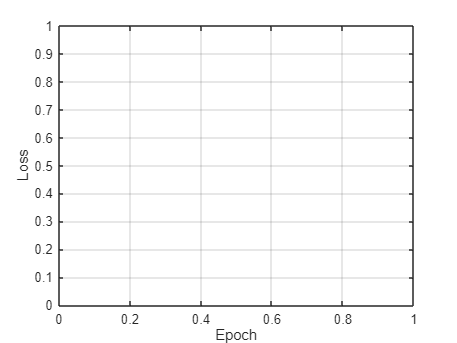

figure;
plot(loss_hist,'LineWidth',2);
xlabel('Epoch'); ylabel('Loss'); grid on;

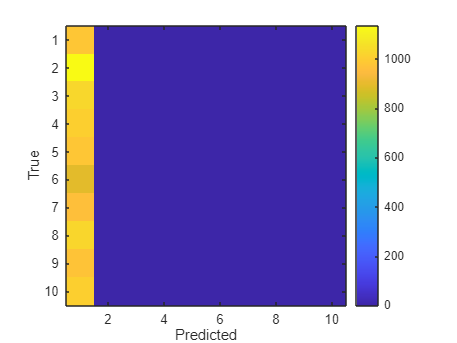

conf_mat = zeros(10,10);
for i=1:length(y_test)
    conf_mat(y_test(i)+1,pred(i)+1) = conf_mat(y_test(i)+1,pred(i)+1)+1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted'); ylabel('True');
axis square;

# **Learning rate change to 1e-2**

d0 = 784; d1 = 128; d2 = 64; d3 = 10;
r1 = min(d1,d0);
r2 = min(d2,d1);
r3 = min(d3,d2);
rng(1);
[U1,~] = qr(randn(d1,r1),0);
[V1,~] = qr(randn(d0,r1),0);
alpha1 = randn(r1,1);
[U2,~] = qr(randn(d2,r2),0);
[V2,~] = qr(randn(d1,r2),0);
alpha2 = randn(r2,1);
[U3,~] = qr(randn(d3,r3),0);
[V3,~] = qr(randn(d2,r3),0);
alpha3 = randn(r3,1);

epochs = 100;
batch_size = 128;
lr = 1e-2;
lambda_orth = 1e-1;
lambda_sparse = 1e-3;
N = size(X_train,2);
num_batches = floor(N/batch_size);
loss_hist = zeros(epochs,1);

for epoch = 1:epochs
    perm = randperm(N);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);
        s1 = exp(alpha1);  S1 = diag(sqrt(s1));
        s2 = exp(alpha2);  S2 = diag(sqrt(s2));
        s3 = exp(alpha3);  S3 = diag(sqrt(s3));
        H1 = S1*(V1'*X);        Z1 = U1*S1*H1;  A1 = max(0,Z1);
        H2 = S2*(V2'*A1);       Z2 = U2*S2*H2;  A2 = max(0,Z2);
        H3 = S3*(V3'*A2);       Z3 = U3*S3*H3;
        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3) ./ sum(exp(Z3),1);
        CE = -sum(sum(Y .* log(Yhat))) / m;
        Orth = ...
            norm(U1'*U1-eye(size(U1,2)),'fro')^2 + norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
            norm(U2'*U2-eye(size(U2,2)),'fro')^2 + norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
            norm(U3'*U3-eye(size(U3,2)),'fro')^2 + norm(V3'*V3-eye(size(V3,2)),'fro')^2;

        Sparse = norm(s1,1)/norm(s1,2) + norm(s2,1)/norm(s2,2) + norm(s3,1)/norm(s3,2);
        loss = CE + lambda_orth*Orth + lambda_sparse*Sparse;
        epoch_loss = epoch_loss + loss;
        dZ3 = Yhat - Y;
        dU3 = (dZ3*(S3*H3)')/m;
        dH3 = (U3*S3)'*dZ3;
        dV3 = (A2*(dH3'*S3))/m;
        ds3 = diag((U3'*dZ3)*H3')/m;
        dU3 = dU3 + 4*lambda_orth*U3*(U3'*U3-eye(size(U3,2)));
        dV3 = dV3 + 4*lambda_orth*V3*(V3'*V3-eye(size(V3,2)));
        ds3 = ds3 + lambda_sparse*( sign(s3)/norm(s3,2) - (norm(s3,1)/(norm(s3,2)^3))*s3 );
        dA2 = V3*(S3*dH3);     dZ2 = dA2 .* (Z2>0);
        dU2 = (dZ2*(S2*H2)')/m;
        dH2 = (U2*S2)'*dZ2;
        dV2 = (A1*(dH2'*S2))/m;
        ds2 = diag((U2'*dZ2)*H2')/m;
        dU2 = dU2 + 4*lambda_orth*U2*(U2'*U2-eye(size(U2,2)));
        dV2 = dV2 + 4*lambda_orth*V2*(V2'*V2-eye(size(V2,2)));
        ds2 = ds2 + lambda_sparse*( sign(s2)/norm(s2,2) - (norm(s2,1)/(norm(s2,2)^3))*s2 );
        dA1 = V2*(S2*dH2);     dZ1 = dA1 .* (Z1>0);
        dU1 = (dZ1*(S1*H1)')/m;
        dH1 = (U1*S1)'*dZ1;
        dV1 = (X*(dH1'*S1))/m;
        ds1 = diag((U1'*dZ1)*H1')/m;
        dU1 = dU1 + 4*lambda_orth*U1*(U1'*U1-eye(size(U1,2)));
        dV1 = dV1 + 4*lambda_orth*V1*(V1'*V1-eye(size(V1,2)));
        ds1 = ds1 + lambda_sparse*( sign(s1)/norm(s1,2) - (norm(s1,1)/(norm(s1,2)^3))*s1 );
        alpha1 = alpha1 - lr*(ds1.*s1);
        alpha2 = alpha2 - lr*(ds2.*s2);
        alpha3 = alpha3 - lr*(ds3.*s3);
        U1 = U1 - lr*dU1;  V1 = V1 - lr*dV1;
        U2 = U2 - lr*dU2;  V2 = V2 - lr*dV2;
        U3 = U3 - lr*dU3;  V3 = V3 - lr*dV3;
    end
    loss_hist(epoch) = epoch_loss/num_batches;
    fprintf('Epoch %d | Loss %.4f\n', epoch, loss_hist(epoch));
end

Epoch 1 | Loss 0.6444
Epoch 2 | Loss 0.3329
Epoch 3 | Loss 0.2702
Epoch 4 | Loss 0.2341
Epoch 5 | Loss 0.2080
Epoch 6 | Loss 0.1897
Epoch 7 | Loss 0.1740
Epoch 8 | Loss 0.1623
Epoch 9 | Loss 0.1530
Epoch 10 | Loss 0.1439
Epoch 11 | Loss 0.1366
Epoch 12 | Loss 0.1291
Epoch 13 | Loss 0.1240
Epoch 14 | Loss 0.1193
Epoch 15 | Loss 0.1141
Epoch 16 | Loss 0.1100
Epoch 17 | Loss 0.1058
Epoch 18 | Loss 0.1025
Epoch 19 | Loss 0.0985
Epoch 20 | Loss 0.0958
Epoch 21 | Loss 0.0916
Epoch 22 | Loss 0.0900
Epoch 23 | Loss 0.0855
Epoch 24 | Loss 0.0842
Epoch 25 | Loss 0.0810
Epoch 26 | Loss 0.0786
Epoch 27 | Loss 0.0754
Epoch 28 | Loss 0.0737
Epoch 29 | Loss 0.0709
Epoch 30 | Loss 0.0675
Epoch 31 | Loss 0.0653
Epoch 32 | Loss 0.0642
Epoch 33 | Loss 0.0640
Epoch 34 | Loss 0.0609
Epoch 35 | Loss 0.0590
Epoch 36 | Loss 0.0581
Epoch 37 | Loss 0.0569
Epoch 38 | Loss 0.0557
Epoch 39 | Loss 0.0515
Epoch 40 | Loss 0.0520
Epoch 41 | Loss 0.0494
Epoch 42 | Loss 0.0497
Epoch 43 | Loss 0.0474
Epoch 44 | Loss 0.04

energy_thresh = 0.99;
prune = @(s) find(cumsum(sort(s.^2,'descend'))/sum(s.^2) >= energy_thresh,1);
r1p = prune(exp(alpha1));
r2p = prune(exp(alpha2));
r3p = prune(exp(alpha3));
[~,i1] = sort(exp(alpha1),'descend');
[~,i2] = sort(exp(alpha2),'descend');
[~,i3] = sort(exp(alpha3),'descend');
U1 = U1(:,i1(1:r1p));  V1 = V1(:,i1(1:r1p));  alpha1 = alpha1(i1(1:r1p));
U2 = U2(:,i2(1:r2p));  V2 = V2(:,i2(1:r2p));  alpha2 = alpha2(i2(1:r2p));
U3 = U3(:,i3(1:r3p));  V3 = V3(:,i3(1:r3p));  alpha3 = alpha3(i3(1:r3p));

S1 = diag(sqrt(exp(alpha1)));
S2 = diag(sqrt(exp(alpha2)));
S3 = diag(sqrt(exp(alpha3)));
H1 = S1*(V1'*X_test);  A1 = max(0,U1*S1*H1);
H2 = S2*(V2'*A1);      A2 = max(0,U2*S2*H2);
H3 = S3*(V3'*A2);      Z3 = U3*S3*H3;
[~,pred] = max(Z3,[],1);
pred = pred - 1;
acc = mean(pred'==y_test)*100;
fprintf('Final Accuracy: %.2f%%\n', acc);

Final Accuracy: 93.03%


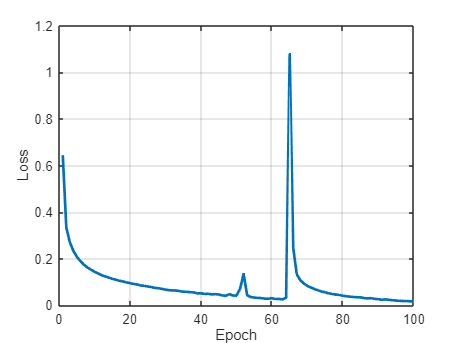

figure;
plot(loss_hist,'LineWidth',2);
xlabel('Epoch'); ylabel('Loss'); grid on;

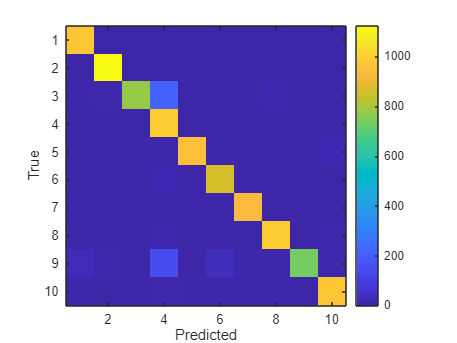

conf_mat = zeros(10,10);
for i=1:length(y_test)
    conf_mat(y_test(i)+1,pred(i)+1) = conf_mat(y_test(i)+1,pred(i)+1)+1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted'); ylabel('True');
axis square;

# **Learning rate change to 1e-3**

d0 = 784; d1 = 128; d2 = 64; d3 = 10;
r1 = min(d1,d0);
r2 = min(d2,d1);
r3 = min(d3,d2);
rng(1);
[U1,~] = qr(randn(d1,r1),0);
[V1,~] = qr(randn(d0,r1),0);
alpha1 = randn(r1,1);
[U2,~] = qr(randn(d2,r2),0);
[V2,~] = qr(randn(d1,r2),0);
alpha2 = randn(r2,1);
[U3,~] = qr(randn(d3,r3),0);
[V3,~] = qr(randn(d2,r3),0);
alpha3 = randn(r3,1);

epochs = 100;
batch_size = 128;
lr = 1e-3;
lambda_orth = 1e-1;
lambda_sparse = 1e-3;
N = size(X_train,2);
num_batches = floor(N/batch_size);
loss_hist = zeros(epochs,1);

for epoch = 1:epochs
    perm = randperm(N);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);
        s1 = exp(alpha1);  S1 = diag(sqrt(s1));
        s2 = exp(alpha2);  S2 = diag(sqrt(s2));
        s3 = exp(alpha3);  S3 = diag(sqrt(s3));
        H1 = S1*(V1'*X);        Z1 = U1*S1*H1;  A1 = max(0,Z1);
        H2 = S2*(V2'*A1);       Z2 = U2*S2*H2;  A2 = max(0,Z2);
        H3 = S3*(V3'*A2);       Z3 = U3*S3*H3;
        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3) ./ sum(exp(Z3),1);
        CE = -sum(sum(Y .* log(Yhat))) / m;
        Orth = ...
            norm(U1'*U1-eye(size(U1,2)),'fro')^2 + norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
            norm(U2'*U2-eye(size(U2,2)),'fro')^2 + norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
            norm(U3'*U3-eye(size(U3,2)),'fro')^2 + norm(V3'*V3-eye(size(V3,2)),'fro')^2;

        Sparse = norm(s1,1)/norm(s1,2) + norm(s2,1)/norm(s2,2) + norm(s3,1)/norm(s3,2);
        loss = CE + lambda_orth*Orth + lambda_sparse*Sparse;
        epoch_loss = epoch_loss + loss;
        dZ3 = Yhat - Y;
        dU3 = (dZ3*(S3*H3)')/m;
        dH3 = (U3*S3)'*dZ3;
        dV3 = (A2*(dH3'*S3))/m;
        ds3 = diag((U3'*dZ3)*H3')/m;
        dU3 = dU3 + 4*lambda_orth*U3*(U3'*U3-eye(size(U3,2)));
        dV3 = dV3 + 4*lambda_orth*V3*(V3'*V3-eye(size(V3,2)));
        ds3 = ds3 + lambda_sparse*( sign(s3)/norm(s3,2) - (norm(s3,1)/(norm(s3,2)^3))*s3 );
        dA2 = V3*(S3*dH3);     dZ2 = dA2 .* (Z2>0);
        dU2 = (dZ2*(S2*H2)')/m;
        dH2 = (U2*S2)'*dZ2;
        dV2 = (A1*(dH2'*S2))/m;
        ds2 = diag((U2'*dZ2)*H2')/m;
        dU2 = dU2 + 4*lambda_orth*U2*(U2'*U2-eye(size(U2,2)));
        dV2 = dV2 + 4*lambda_orth*V2*(V2'*V2-eye(size(V2,2)));
        ds2 = ds2 + lambda_sparse*( sign(s2)/norm(s2,2) - (norm(s2,1)/(norm(s2,2)^3))*s2 );
        dA1 = V2*(S2*dH2);     dZ1 = dA1 .* (Z1>0);
        dU1 = (dZ1*(S1*H1)')/m;
        dH1 = (U1*S1)'*dZ1;
        dV1 = (X*(dH1'*S1))/m;
        ds1 = diag((U1'*dZ1)*H1')/m;
        dU1 = dU1 + 4*lambda_orth*U1*(U1'*U1-eye(size(U1,2)));
        dV1 = dV1 + 4*lambda_orth*V1*(V1'*V1-eye(size(V1,2)));
        ds1 = ds1 + lambda_sparse*( sign(s1)/norm(s1,2) - (norm(s1,1)/(norm(s1,2)^3))*s1 );
        alpha1 = alpha1 - lr*(ds1.*s1);
        alpha2 = alpha2 - lr*(ds2.*s2);
        alpha3 = alpha3 - lr*(ds3.*s3);
        U1 = U1 - lr*dU1;  V1 = V1 - lr*dV1;
        U2 = U2 - lr*dU2;  V2 = V2 - lr*dV2;
        U3 = U3 - lr*dU3;  V3 = V3 - lr*dV3;
    end
    loss_hist(epoch) = epoch_loss/num_batches;
    fprintf('Epoch %d | Loss %.4f\n', epoch, loss_hist(epoch));
end

Epoch 1 | Loss 1.3716
Epoch 2 | Loss 0.7982
Epoch 3 | Loss 0.6261
Epoch 4 | Loss 0.5353
Epoch 5 | Loss 0.4802
Epoch 6 | Loss 0.4417
Epoch 7 | Loss 0.4127
Epoch 8 | Loss 0.3900
Epoch 9 | Loss 0.3707
Epoch 10 | Loss 0.3549
Epoch 11 | Loss 0.3410
Epoch 12 | Loss 0.3297
Epoch 13 | Loss 0.3184
Epoch 14 | Loss 0.3093
Epoch 15 | Loss 0.3005
Epoch 16 | Loss 0.2932
Epoch 17 | Loss 0.2859
Epoch 18 | Loss 0.2791
Epoch 19 | Loss 0.2728
Epoch 20 | Loss 0.2672
Epoch 21 | Loss 0.2615
Epoch 22 | Loss 0.2568
Epoch 23 | Loss 0.2513
Epoch 24 | Loss 0.2467
Epoch 25 | Loss 0.2422
Epoch 26 | Loss 0.2385
Epoch 27 | Loss 0.2344
Epoch 28 | Loss 0.2303
Epoch 29 | Loss 0.2263
Epoch 30 | Loss 0.2228
Epoch 31 | Loss 0.2194
Epoch 32 | Loss 0.2161
Epoch 33 | Loss 0.2131
Epoch 34 | Loss 0.2102
Epoch 35 | Loss 0.2069
Epoch 36 | Loss 0.2042
Epoch 37 | Loss 0.2022
Epoch 38 | Loss 0.1989
Epoch 39 | Loss 0.1958
Epoch 40 | Loss 0.1940
Epoch 41 | Loss 0.1911
Epoch 42 | Loss 0.1888
Epoch 43 | Loss 0.1861
Epoch 44 | Loss 0.18

energy_thresh = 0.99;
prune = @(s) find(cumsum(sort(s.^2,'descend'))/sum(s.^2) >= energy_thresh,1);
r1p = prune(exp(alpha1));
r2p = prune(exp(alpha2));
r3p = prune(exp(alpha3));
[~,i1] = sort(exp(alpha1),'descend');
[~,i2] = sort(exp(alpha2),'descend');
[~,i3] = sort(exp(alpha3),'descend');
U1 = U1(:,i1(1:r1p));  V1 = V1(:,i1(1:r1p));  alpha1 = alpha1(i1(1:r1p));
U2 = U2(:,i2(1:r2p));  V2 = V2(:,i2(1:r2p));  alpha2 = alpha2(i2(1:r2p));
U3 = U3(:,i3(1:r3p));  V3 = V3(:,i3(1:r3p));  alpha3 = alpha3(i3(1:r3p));

S1 = diag(sqrt(exp(alpha1)));
S2 = diag(sqrt(exp(alpha2)));
S3 = diag(sqrt(exp(alpha3)));
H1 = S1*(V1'*X_test);  A1 = max(0,U1*S1*H1);
H2 = S2*(V2'*A1);      A2 = max(0,U2*S2*H2);
H3 = S3*(V3'*A2);      Z3 = U3*S3*H3;
[~,pred] = max(Z3,[],1);
pred = pred - 1;
acc = mean(pred'==y_test)*100;
fprintf('Final Accuracy: %.2f%%\n', acc);

Final Accuracy: 93.37%


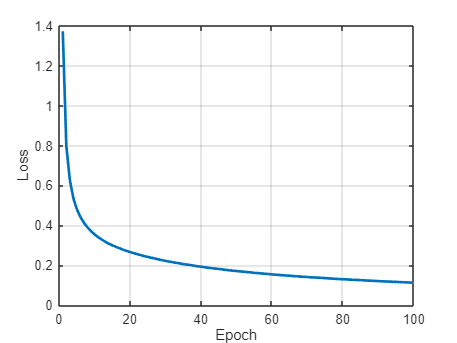

figure;
plot(loss_hist,'LineWidth',2);
xlabel('Epoch'); ylabel('Loss'); grid on;

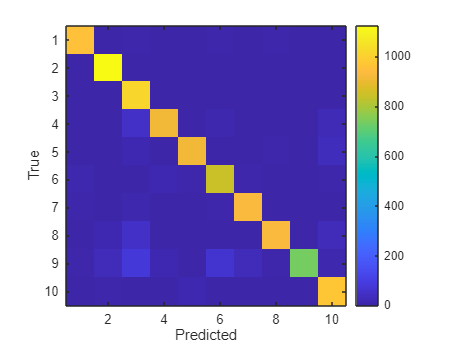

conf_mat = zeros(10,10);
for i=1:length(y_test)
    conf_mat(y_test(i)+1,pred(i)+1) = conf_mat(y_test(i)+1,pred(i)+1)+1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted'); ylabel('True');
axis square;

# **Learning rate change to 1e-4**

d0 = 784; d1 = 128; d2 = 64; d3 = 10;
r1 = min(d1,d0);
r2 = min(d2,d1);
r3 = min(d3,d2);
rng(1);
[U1,~] = qr(randn(d1,r1),0);
[V1,~] = qr(randn(d0,r1),0);
alpha1 = randn(r1,1);
[U2,~] = qr(randn(d2,r2),0);
[V2,~] = qr(randn(d1,r2),0);
alpha2 = randn(r2,1);
[U3,~] = qr(randn(d3,r3),0);
[V3,~] = qr(randn(d2,r3),0);
alpha3 = randn(r3,1);

epochs = 100;
batch_size = 128;
lr = 1e-4;
lambda_orth = 1e-1;
lambda_sparse = 1e-3;
N = size(X_train,2);
num_batches = floor(N/batch_size);
loss_hist = zeros(epochs,1);

for epoch = 1:epochs
    perm = randperm(N);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);
        s1 = exp(alpha1);  S1 = diag(sqrt(s1));
        s2 = exp(alpha2);  S2 = diag(sqrt(s2));
        s3 = exp(alpha3);  S3 = diag(sqrt(s3));
        H1 = S1*(V1'*X);        Z1 = U1*S1*H1;  A1 = max(0,Z1);
        H2 = S2*(V2'*A1);       Z2 = U2*S2*H2;  A2 = max(0,Z2);
        H3 = S3*(V3'*A2);       Z3 = U3*S3*H3;
        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3) ./ sum(exp(Z3),1);
        CE = -sum(sum(Y .* log(Yhat))) / m;
        Orth = ...
            norm(U1'*U1-eye(size(U1,2)),'fro')^2 + norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
            norm(U2'*U2-eye(size(U2,2)),'fro')^2 + norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
            norm(U3'*U3-eye(size(U3,2)),'fro')^2 + norm(V3'*V3-eye(size(V3,2)),'fro')^2;

        Sparse = norm(s1,1)/norm(s1,2) + norm(s2,1)/norm(s2,2) + norm(s3,1)/norm(s3,2);
        loss = CE + lambda_orth*Orth + lambda_sparse*Sparse;
        epoch_loss = epoch_loss + loss;
        dZ3 = Yhat - Y;
        dU3 = (dZ3*(S3*H3)')/m;
        dH3 = (U3*S3)'*dZ3;
        dV3 = (A2*(dH3'*S3))/m;
        ds3 = diag((U3'*dZ3)*H3')/m;
        dU3 = dU3 + 4*lambda_orth*U3*(U3'*U3-eye(size(U3,2)));
        dV3 = dV3 + 4*lambda_orth*V3*(V3'*V3-eye(size(V3,2)));
        ds3 = ds3 + lambda_sparse*( sign(s3)/norm(s3,2) - (norm(s3,1)/(norm(s3,2)^3))*s3 );
        dA2 = V3*(S3*dH3);     dZ2 = dA2 .* (Z2>0);
        dU2 = (dZ2*(S2*H2)')/m;
        dH2 = (U2*S2)'*dZ2;
        dV2 = (A1*(dH2'*S2))/m;
        ds2 = diag((U2'*dZ2)*H2')/m;
        dU2 = dU2 + 4*lambda_orth*U2*(U2'*U2-eye(size(U2,2)));
        dV2 = dV2 + 4*lambda_orth*V2*(V2'*V2-eye(size(V2,2)));
        ds2 = ds2 + lambda_sparse*( sign(s2)/norm(s2,2) - (norm(s2,1)/(norm(s2,2)^3))*s2 );
        dA1 = V2*(S2*dH2);     dZ1 = dA1 .* (Z1>0);
        dU1 = (dZ1*(S1*H1)')/m;
        dH1 = (U1*S1)'*dZ1;
        dV1 = (X*(dH1'*S1))/m;
        ds1 = diag((U1'*dZ1)*H1')/m;
        dU1 = dU1 + 4*lambda_orth*U1*(U1'*U1-eye(size(U1,2)));
        dV1 = dV1 + 4*lambda_orth*V1*(V1'*V1-eye(size(V1,2)));
        ds1 = ds1 + lambda_sparse*( sign(s1)/norm(s1,2) - (norm(s1,1)/(norm(s1,2)^3))*s1 );
        alpha1 = alpha1 - lr*(ds1.*s1);
        alpha2 = alpha2 - lr*(ds2.*s2);
        alpha3 = alpha3 - lr*(ds3.*s3);
        U1 = U1 - lr*dU1;  V1 = V1 - lr*dV1;
        U2 = U2 - lr*dU2;  V2 = V2 - lr*dV2;
        U3 = U3 - lr*dU3;  V3 = V3 - lr*dV3;
    end
    loss_hist(epoch) = epoch_loss/num_batches;
    fprintf('Epoch %d | Loss %.4f\n', epoch, loss_hist(epoch));
end

Epoch 1 | Loss 2.2187
Epoch 2 | Loss 1.8437
Epoch 3 | Loss 1.6063
Epoch 4 | Loss 1.4220
Epoch 5 | Loss 1.2834
Epoch 6 | Loss 1.1822
Epoch 7 | Loss 1.1050
Epoch 8 | Loss 1.0436
Epoch 9 | Loss 0.9929
Epoch 10 | Loss 0.9494
Epoch 11 | Loss 0.9117
Epoch 12 | Loss 0.8778
Epoch 13 | Loss 0.8478
Epoch 14 | Loss 0.8202
Epoch 15 | Loss 0.7948
Epoch 16 | Loss 0.7719
Epoch 17 | Loss 0.7501
Epoch 18 | Loss 0.7303
Epoch 19 | Loss 0.7115
Epoch 20 | Loss 0.6940
Epoch 21 | Loss 0.6774
Epoch 22 | Loss 0.6620
Epoch 23 | Loss 0.6474
Epoch 24 | Loss 0.6342
Epoch 25 | Loss 0.6216
Epoch 26 | Loss 0.6100
Epoch 27 | Loss 0.5989
Epoch 28 | Loss 0.5884
Epoch 29 | Loss 0.5790
Epoch 30 | Loss 0.5697
Epoch 31 | Loss 0.5610
Epoch 32 | Loss 0.5529
Epoch 33 | Loss 0.5451
Epoch 34 | Loss 0.5382
Epoch 35 | Loss 0.5309
Epoch 36 | Loss 0.5243
Epoch 37 | Loss 0.5185
Epoch 38 | Loss 0.5123
Epoch 39 | Loss 0.5062
Epoch 40 | Loss 0.5010
Epoch 41 | Loss 0.4956
Epoch 42 | Loss 0.4905
Epoch 43 | Loss 0.4853
Epoch 44 | Loss 0.48

energy_thresh = 0.99;
prune = @(s) find(cumsum(sort(s.^2,'descend'))/sum(s.^2) >= energy_thresh,1);
r1p = prune(exp(alpha1));
r2p = prune(exp(alpha2));
r3p = prune(exp(alpha3));
[~,i1] = sort(exp(alpha1),'descend');
[~,i2] = sort(exp(alpha2),'descend');
[~,i3] = sort(exp(alpha3),'descend');
U1 = U1(:,i1(1:r1p));  V1 = V1(:,i1(1:r1p));  alpha1 = alpha1(i1(1:r1p));
U2 = U2(:,i2(1:r2p));  V2 = V2(:,i2(1:r2p));  alpha2 = alpha2(i2(1:r2p));
U3 = U3(:,i3(1:r3p));  V3 = V3(:,i3(1:r3p));  alpha3 = alpha3(i3(1:r3p));

S1 = diag(sqrt(exp(alpha1)));
S2 = diag(sqrt(exp(alpha2)));
S3 = diag(sqrt(exp(alpha3)));
H1 = S1*(V1'*X_test);  A1 = max(0,U1*S1*H1);
H2 = S2*(V2'*A1);      A2 = max(0,U2*S2*H2);
H3 = S3*(V3'*A2);      Z3 = U3*S3*H3;
[~,pred] = max(Z3,[],1);
pred = pred - 1;
acc = mean(pred'==y_test)*100;
fprintf('Final Accuracy: %.2f%%\n', acc);

Final Accuracy: 86.35%


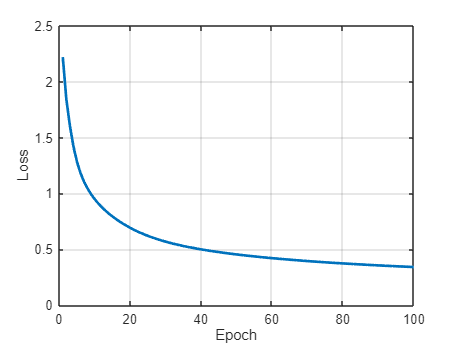

figure;
plot(loss_hist,'LineWidth',2);
xlabel('Epoch'); ylabel('Loss'); grid on;

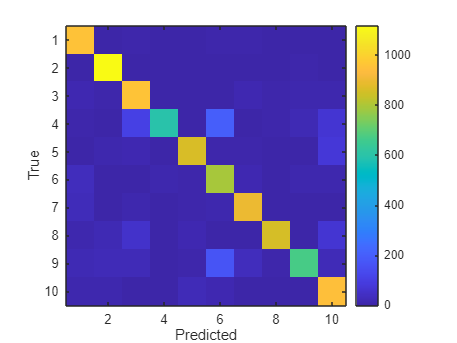

conf_mat = zeros(10,10);
for i=1:length(y_test)
    conf_mat(y_test(i)+1,pred(i)+1) = conf_mat(y_test(i)+1,pred(i)+1)+1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted'); ylabel('True');
axis square;

# **Learning rate change to 1e-5**

d0 = 784; d1 = 128; d2 = 64; d3 = 10;
r1 = min(d1,d0);
r2 = min(d2,d1);
r3 = min(d3,d2);
rng(1);
[U1,~] = qr(randn(d1,r1),0);
[V1,~] = qr(randn(d0,r1),0);
alpha1 = randn(r1,1);
[U2,~] = qr(randn(d2,r2),0);
[V2,~] = qr(randn(d1,r2),0);
alpha2 = randn(r2,1);
[U3,~] = qr(randn(d3,r3),0);
[V3,~] = qr(randn(d2,r3),0);
alpha3 = randn(r3,1);

epochs = 100;
batch_size = 128;
lr = 1e-5;
lambda_orth = 1e-1;
lambda_sparse = 1e-3;
N = size(X_train,2);
num_batches = floor(N/batch_size);
loss_hist = zeros(epochs,1);

for epoch = 1:epochs
    perm = randperm(N);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);
        s1 = exp(alpha1);  S1 = diag(sqrt(s1));
        s2 = exp(alpha2);  S2 = diag(sqrt(s2));
        s3 = exp(alpha3);  S3 = diag(sqrt(s3));
        H1 = S1*(V1'*X);        Z1 = U1*S1*H1;  A1 = max(0,Z1);
        H2 = S2*(V2'*A1);       Z2 = U2*S2*H2;  A2 = max(0,Z2);
        H3 = S3*(V3'*A2);       Z3 = U3*S3*H3;
        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3) ./ sum(exp(Z3),1);
        CE = -sum(sum(Y .* log(Yhat))) / m;
        Orth = ...
            norm(U1'*U1-eye(size(U1,2)),'fro')^2 + norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
            norm(U2'*U2-eye(size(U2,2)),'fro')^2 + norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
            norm(U3'*U3-eye(size(U3,2)),'fro')^2 + norm(V3'*V3-eye(size(V3,2)),'fro')^2;

        Sparse = norm(s1,1)/norm(s1,2) + norm(s2,1)/norm(s2,2) + norm(s3,1)/norm(s3,2);
        loss = CE + lambda_orth*Orth + lambda_sparse*Sparse;
        epoch_loss = epoch_loss + loss;
        dZ3 = Yhat - Y;
        dU3 = (dZ3*(S3*H3)')/m;
        dH3 = (U3*S3)'*dZ3;
        dV3 = (A2*(dH3'*S3))/m;
        ds3 = diag((U3'*dZ3)*H3')/m;
        dU3 = dU3 + 4*lambda_orth*U3*(U3'*U3-eye(size(U3,2)));
        dV3 = dV3 + 4*lambda_orth*V3*(V3'*V3-eye(size(V3,2)));
        ds3 = ds3 + lambda_sparse*( sign(s3)/norm(s3,2) - (norm(s3,1)/(norm(s3,2)^3))*s3 );
        dA2 = V3*(S3*dH3);     dZ2 = dA2 .* (Z2>0);
        dU2 = (dZ2*(S2*H2)')/m;
        dH2 = (U2*S2)'*dZ2;
        dV2 = (A1*(dH2'*S2))/m;
        ds2 = diag((U2'*dZ2)*H2')/m;
        dU2 = dU2 + 4*lambda_orth*U2*(U2'*U2-eye(size(U2,2)));
        dV2 = dV2 + 4*lambda_orth*V2*(V2'*V2-eye(size(V2,2)));
        ds2 = ds2 + lambda_sparse*( sign(s2)/norm(s2,2) - (norm(s2,1)/(norm(s2,2)^3))*s2 );
        dA1 = V2*(S2*dH2);     dZ1 = dA1 .* (Z1>0);
        dU1 = (dZ1*(S1*H1)')/m;
        dH1 = (U1*S1)'*dZ1;
        dV1 = (X*(dH1'*S1))/m;
        ds1 = diag((U1'*dZ1)*H1')/m;
        dU1 = dU1 + 4*lambda_orth*U1*(U1'*U1-eye(size(U1,2)));
        dV1 = dV1 + 4*lambda_orth*V1*(V1'*V1-eye(size(V1,2)));
        ds1 = ds1 + lambda_sparse*( sign(s1)/norm(s1,2) - (norm(s1,1)/(norm(s1,2)^3))*s1 );
        alpha1 = alpha1 - lr*(ds1.*s1);
        alpha2 = alpha2 - lr*(ds2.*s2);
        alpha3 = alpha3 - lr*(ds3.*s3);
        U1 = U1 - lr*dU1;  V1 = V1 - lr*dV1;
        U2 = U2 - lr*dU2;  V2 = V2 - lr*dV2;
        U3 = U3 - lr*dU3;  V3 = V3 - lr*dV3;
    end
    loss_hist(epoch) = epoch_loss/num_batches;
    fprintf('Epoch %d | Loss %.4f\n', epoch, loss_hist(epoch));
end

Epoch 1 | Loss 2.5923
Epoch 2 | Loss 2.4258
Epoch 3 | Loss 2.3313
Epoch 4 | Loss 2.2622
Epoch 5 | Loss 2.2048
Epoch 6 | Loss 2.1555
Epoch 7 | Loss 2.1117
Epoch 8 | Loss 2.0722
Epoch 9 | Loss 2.0359
Epoch 10 | Loss 2.0018
Epoch 11 | Loss 1.9698
Epoch 12 | Loss 1.9389
Epoch 13 | Loss 1.9096
Epoch 14 | Loss 1.8811
Epoch 15 | Loss 1.8534
Epoch 16 | Loss 1.8268
Epoch 17 | Loss 1.8005
Epoch 18 | Loss 1.7751
Epoch 19 | Loss 1.7503
Epoch 20 | Loss 1.7262
Epoch 21 | Loss 1.7025
Epoch 22 | Loss 1.6795
Epoch 23 | Loss 1.6571
Epoch 24 | Loss 1.6350
Epoch 25 | Loss 1.6141
Epoch 26 | Loss 1.5934
Epoch 27 | Loss 1.5726
Epoch 28 | Loss 1.5529
Epoch 29 | Loss 1.5336
Epoch 30 | Loss 1.5150
Epoch 31 | Loss 1.4963
Epoch 32 | Loss 1.4784
Epoch 33 | Loss 1.4610
Epoch 34 | Loss 1.4441
Epoch 35 | Loss 1.4274
Epoch 36 | Loss 1.4114
Epoch 37 | Loss 1.3961
Epoch 38 | Loss 1.3808
Epoch 39 | Loss 1.3662
Epoch 40 | Loss 1.3520
Epoch 41 | Loss 1.3382
Epoch 42 | Loss 1.3251
Epoch 43 | Loss 1.3120
Epoch 44 | Loss 1.29

energy_thresh = 0.99;
prune = @(s) find(cumsum(sort(s.^2,'descend'))/sum(s.^2) >= energy_thresh,1);
r1p = prune(exp(alpha1));
r2p = prune(exp(alpha2));
r3p = prune(exp(alpha3));
[~,i1] = sort(exp(alpha1),'descend');
[~,i2] = sort(exp(alpha2),'descend');
[~,i3] = sort(exp(alpha3),'descend');
U1 = U1(:,i1(1:r1p));  V1 = V1(:,i1(1:r1p));  alpha1 = alpha1(i1(1:r1p));
U2 = U2(:,i2(1:r2p));  V2 = V2(:,i2(1:r2p));  alpha2 = alpha2(i2(1:r2p));
U3 = U3(:,i3(1:r3p));  V3 = V3(:,i3(1:r3p));  alpha3 = alpha3(i3(1:r3p));

S1 = diag(sqrt(exp(alpha1)));
S2 = diag(sqrt(exp(alpha2)));
S3 = diag(sqrt(exp(alpha3)));
H1 = S1*(V1'*X_test);  A1 = max(0,U1*S1*H1);
H2 = S2*(V2'*A1);      A2 = max(0,U2*S2*H2);
H3 = S3*(V3'*A2);      Z3 = U3*S3*H3;
[~,pred] = max(Z3,[],1);
pred = pred - 1;
acc = mean(pred'==y_test)*100;
fprintf('Final Accuracy: %.2f%%\n', acc);

Final Accuracy: 64.07%


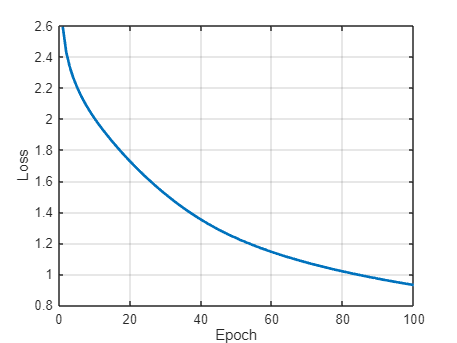

figure;
plot(loss_hist,'LineWidth',2);
xlabel('Epoch'); ylabel('Loss'); grid on;

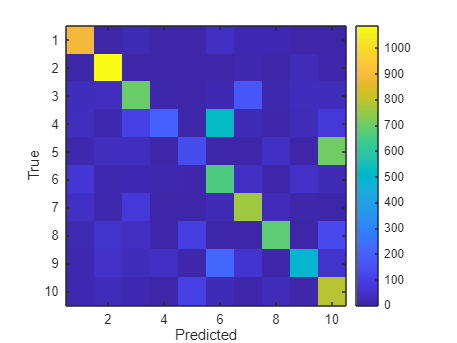

conf_mat = zeros(10,10);
for i=1:length(y_test)
    conf_mat(y_test(i)+1,pred(i)+1) = conf_mat(y_test(i)+1,pred(i)+1)+1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted'); ylabel('True');
axis square;

# **Learning rate change to 1e-6**

d0 = 784; d1 = 128; d2 = 64; d3 = 10;
r1 = min(d1,d0);
r2 = min(d2,d1);
r3 = min(d3,d2);
rng(1);
[U1,~] = qr(randn(d1,r1),0);
[V1,~] = qr(randn(d0,r1),0);
alpha1 = randn(r1,1);
[U2,~] = qr(randn(d2,r2),0);
[V2,~] = qr(randn(d1,r2),0);
alpha2 = randn(r2,1);
[U3,~] = qr(randn(d3,r3),0);
[V3,~] = qr(randn(d2,r3),0);
alpha3 = randn(r3,1);

epochs = 100;
batch_size = 128;
lr = 1e-6;
lambda_orth = 1e-1;
lambda_sparse = 1e-3;
N = size(X_train,2);
num_batches = floor(N/batch_size);
loss_hist = zeros(epochs,1);

for epoch = 1:epochs
    perm = randperm(N);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);
        s1 = exp(alpha1);  S1 = diag(sqrt(s1));
        s2 = exp(alpha2);  S2 = diag(sqrt(s2));
        s3 = exp(alpha3);  S3 = diag(sqrt(s3));
        H1 = S1*(V1'*X);        Z1 = U1*S1*H1;  A1 = max(0,Z1);
        H2 = S2*(V2'*A1);       Z2 = U2*S2*H2;  A2 = max(0,Z2);
        H3 = S3*(V3'*A2);       Z3 = U3*S3*H3;
        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3) ./ sum(exp(Z3),1);
        CE = -sum(sum(Y .* log(Yhat))) / m;
        Orth = ...
            norm(U1'*U1-eye(size(U1,2)),'fro')^2 + norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
            norm(U2'*U2-eye(size(U2,2)),'fro')^2 + norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
            norm(U3'*U3-eye(size(U3,2)),'fro')^2 + norm(V3'*V3-eye(size(V3,2)),'fro')^2;

        Sparse = norm(s1,1)/norm(s1,2) + norm(s2,1)/norm(s2,2) + norm(s3,1)/norm(s3,2);
        loss = CE + lambda_orth*Orth + lambda_sparse*Sparse;
        epoch_loss = epoch_loss + loss;
        dZ3 = Yhat - Y;
        dU3 = (dZ3*(S3*H3)')/m;
        dH3 = (U3*S3)'*dZ3;
        dV3 = (A2*(dH3'*S3))/m;
        ds3 = diag((U3'*dZ3)*H3')/m;
        dU3 = dU3 + 4*lambda_orth*U3*(U3'*U3-eye(size(U3,2)));
        dV3 = dV3 + 4*lambda_orth*V3*(V3'*V3-eye(size(V3,2)));
        ds3 = ds3 + lambda_sparse*( sign(s3)/norm(s3,2) - (norm(s3,1)/(norm(s3,2)^3))*s3 );
        dA2 = V3*(S3*dH3);     dZ2 = dA2 .* (Z2>0);
        dU2 = (dZ2*(S2*H2)')/m;
        dH2 = (U2*S2)'*dZ2;
        dV2 = (A1*(dH2'*S2))/m;
        ds2 = diag((U2'*dZ2)*H2')/m;
        dU2 = dU2 + 4*lambda_orth*U2*(U2'*U2-eye(size(U2,2)));
        dV2 = dV2 + 4*lambda_orth*V2*(V2'*V2-eye(size(V2,2)));
        ds2 = ds2 + lambda_sparse*( sign(s2)/norm(s2,2) - (norm(s2,1)/(norm(s2,2)^3))*s2 );
        dA1 = V2*(S2*dH2);     dZ1 = dA1 .* (Z1>0);
        dU1 = (dZ1*(S1*H1)')/m;
        dH1 = (U1*S1)'*dZ1;
        dV1 = (X*(dH1'*S1))/m;
        ds1 = diag((U1'*dZ1)*H1')/m;
        dU1 = dU1 + 4*lambda_orth*U1*(U1'*U1-eye(size(U1,2)));
        dV1 = dV1 + 4*lambda_orth*V1*(V1'*V1-eye(size(V1,2)));
        ds1 = ds1 + lambda_sparse*( sign(s1)/norm(s1,2) - (norm(s1,1)/(norm(s1,2)^3))*s1 );
        alpha1 = alpha1 - lr*(ds1.*s1);
        alpha2 = alpha2 - lr*(ds2.*s2);
        alpha3 = alpha3 - lr*(ds3.*s3);
        U1 = U1 - lr*dU1;  V1 = V1 - lr*dV1;
        U2 = U2 - lr*dU2;  V2 = V2 - lr*dV2;
        U3 = U3 - lr*dU3;  V3 = V3 - lr*dV3;
    end
    loss_hist(epoch) = epoch_loss/num_batches;
    fprintf('Epoch %d | Loss %.4f\n', epoch, loss_hist(epoch));
end

Epoch 1 | Loss 2.7149
Epoch 2 | Loss 2.6797
Epoch 3 | Loss 2.6480
Epoch 4 | Loss 2.6202
Epoch 5 | Loss 2.5947
Epoch 6 | Loss 2.5716
Epoch 7 | Loss 2.5504
Epoch 8 | Loss 2.5311
Epoch 9 | Loss 2.5132
Epoch 10 | Loss 2.4965
Epoch 11 | Loss 2.4810
Epoch 12 | Loss 2.4666
Epoch 13 | Loss 2.4535
Epoch 14 | Loss 2.4407
Epoch 15 | Loss 2.4286
Epoch 16 | Loss 2.4174
Epoch 17 | Loss 2.4066
Epoch 18 | Loss 2.3961
Epoch 19 | Loss 2.3863
Epoch 20 | Loss 2.3767
Epoch 21 | Loss 2.3676
Epoch 22 | Loss 2.3589
Epoch 23 | Loss 2.3505
Epoch 24 | Loss 2.3420
Epoch 25 | Loss 2.3342
Epoch 26 | Loss 2.3264
Epoch 27 | Loss 2.3187
Epoch 28 | Loss 2.3114
Epoch 29 | Loss 2.3044
Epoch 30 | Loss 2.2975
Epoch 31 | Loss 2.2905
Epoch 32 | Loss 2.2840
Epoch 33 | Loss 2.2774
Epoch 34 | Loss 2.2710
Epoch 35 | Loss 2.2647
Epoch 36 | Loss 2.2584
Epoch 37 | Loss 2.2525
Epoch 38 | Loss 2.2464
Epoch 39 | Loss 2.2405
Epoch 40 | Loss 2.2347
Epoch 41 | Loss 2.2291
Epoch 42 | Loss 2.2235
Epoch 43 | Loss 2.2180
Epoch 44 | Loss 2.21

energy_thresh = 0.99;
prune = @(s) find(cumsum(sort(s.^2,'descend'))/sum(s.^2) >= energy_thresh,1);
r1p = prune(exp(alpha1));
r2p = prune(exp(alpha2));
r3p = prune(exp(alpha3));
[~,i1] = sort(exp(alpha1),'descend');
[~,i2] = sort(exp(alpha2),'descend');
[~,i3] = sort(exp(alpha3),'descend');
U1 = U1(:,i1(1:r1p));  V1 = V1(:,i1(1:r1p));  alpha1 = alpha1(i1(1:r1p));
U2 = U2(:,i2(1:r2p));  V2 = V2(:,i2(1:r2p));  alpha2 = alpha2(i2(1:r2p));
U3 = U3(:,i3(1:r3p));  V3 = V3(:,i3(1:r3p));  alpha3 = alpha3(i3(1:r3p));

S1 = diag(sqrt(exp(alpha1)));
S2 = diag(sqrt(exp(alpha2)));
S3 = diag(sqrt(exp(alpha3)));
H1 = S1*(V1'*X_test);  A1 = max(0,U1*S1*H1);
H2 = S2*(V2'*A1);      A2 = max(0,U2*S2*H2);
H3 = S3*(V3'*A2);      Z3 = U3*S3*H3;
[~,pred] = max(Z3,[],1);
pred = pred - 1;
acc = mean(pred'==y_test)*100;
fprintf('Final Accuracy: %.2f%%\n', acc);

Final Accuracy: 31.85%


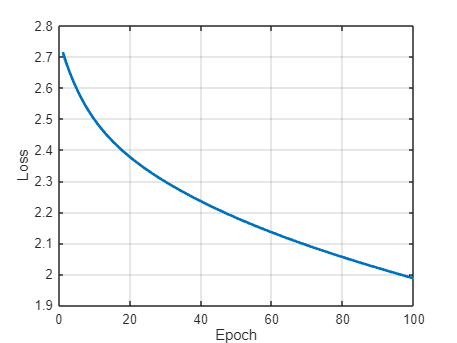

figure;
plot(loss_hist,'LineWidth',2);
xlabel('Epoch'); ylabel('Loss'); grid on;

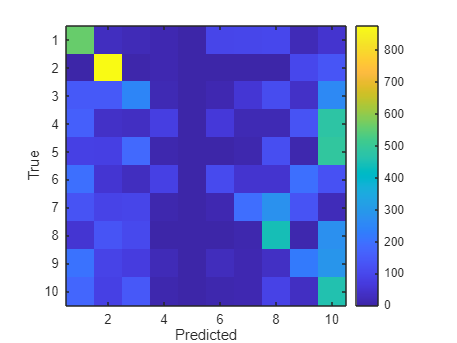

conf_mat = zeros(10,10);
for i=1:length(y_test)
    conf_mat(y_test(i)+1,pred(i)+1) = conf_mat(y_test(i)+1,pred(i)+1)+1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted'); ylabel('True');
axis square;